syms x y c

% let
a = 4;

phi(x, y) = (a .* x.^3)/3 - (a .* x .* y.^2) - 2;

u = diff(phi, x);
v = diff(phi, y);

% (a)
subplot(1, 2, 1)
[x, y] = meshgrid(-4:0.4:4, -5:0.4:5);
uu = u(x, y);
vv = v(x, y);
streamslice(x, y, uu, vv)
title('Equipotential Curves')
% (b)
syms x y c
st_func = int(u, y) - int(v, x) + c

$$st\_func(x, y) = 8\,x^{2}\,y-\frac{4\,y^{3}}{3}+c$$

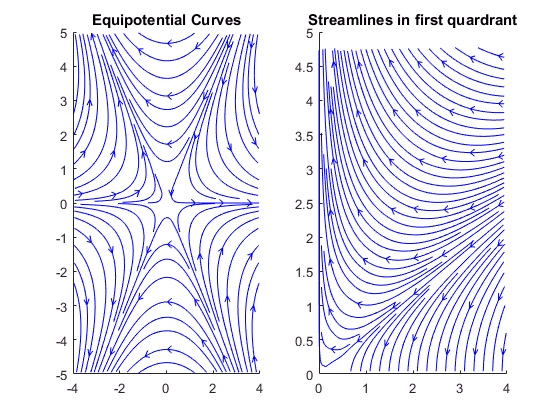

% (c)
subplot(1, 2, 2)
[x, y] = meshgrid(0:0.4:4, 0:0.4:5);
uv = v(x, y);
vu = -u(x, y);
streamslice(x, y, uv, vu)
title('Streamlines in first quardrant')